s = daq.createSession('ni');
dev = daq.getDevices().ID;
addAnalogOutputChannel(s, dev, 'ao0','Voltage'); 
addAnalogInputChannel(s, dev, 'ai0', 'Voltage');
addAnalogInputChannel(s, dev, 'ai1', 'Voltage'); % current

s.Rate = 1000;

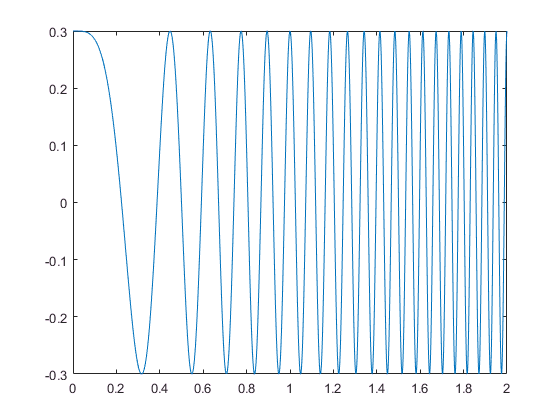

t = 0:1/1e3:2;
y = 0.3*chirp(t,0,1,10);
plot(t, y)

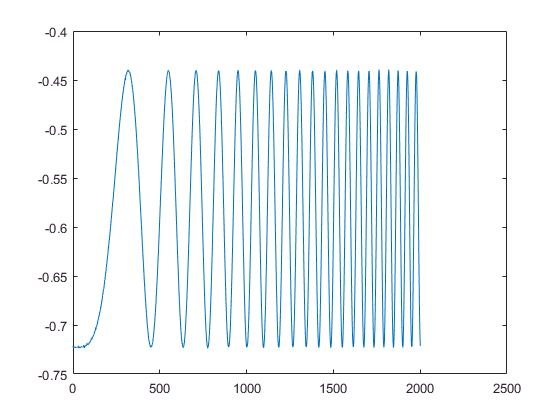

queueOutputData(s, y')
output = s.startForeground();

plot(output(:,2))

time = datestr(datetime);
time = strrep(time, ':', '-');
filename = strcat(time, '-chirp', '.csv');
csvwrite(filename, output);